# Experiment 2

# Frequency Modulation (FM) and Demodulation

## Communications Lab

## *190020039*

### Initialize Matlab

close all;
clear;
clc;

### Declaring some variables

fs=500; % sampling frequency
t=0:1/fs:10; % time array from 0 to 10 with spacing of 1/fs
fc=10; % carrier frequency

### Message signal and plots

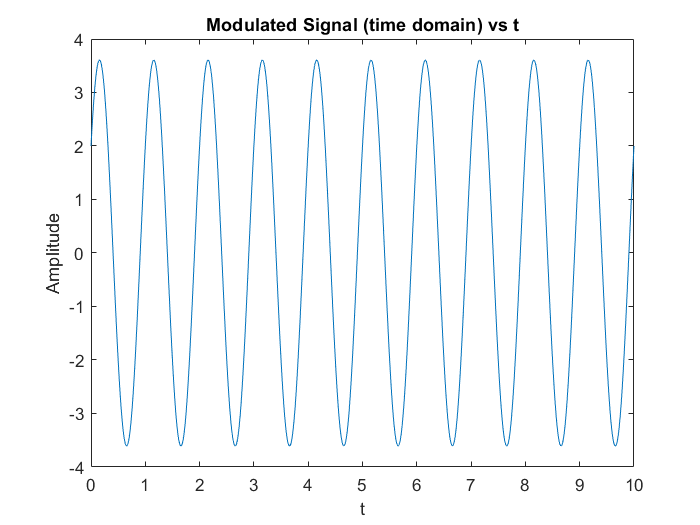

m=3*sin(2*pi*t)+2*cos(2*pi*t); % message signal array
% plot of message signal vs time
plot(t,m)
title("Modulated Signal (time domain) vs t");
xlabel("t");
ylabel("Amplitude");

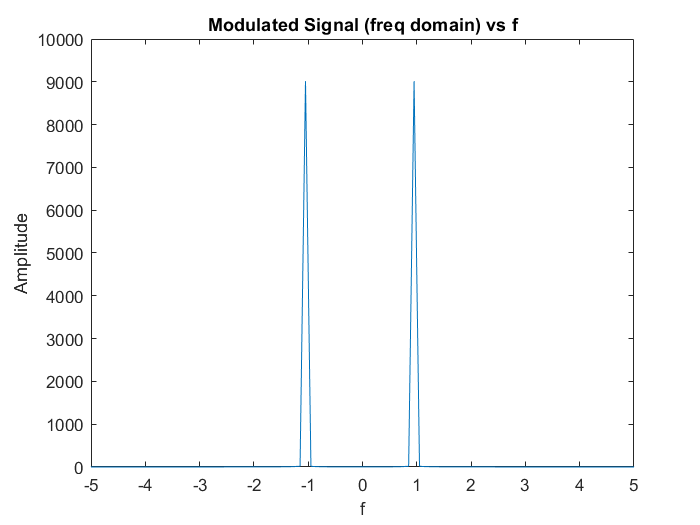

M=fftshift(fft(m)); % fourier transform of message signal array
n=length(M); % no of elements in M
f=(-n/2:n/2-1)*fs/n; % freq array for message signal
% plotting freq domain plot of message signal
plot(f,abs(M))
xlabel('f');
ylabel('Amplitude');
title('Modulated Signal (freq domain) vs f');
xlim([-fc/2 fc/2]);% x limits changed for better plot

### Modulation and plots

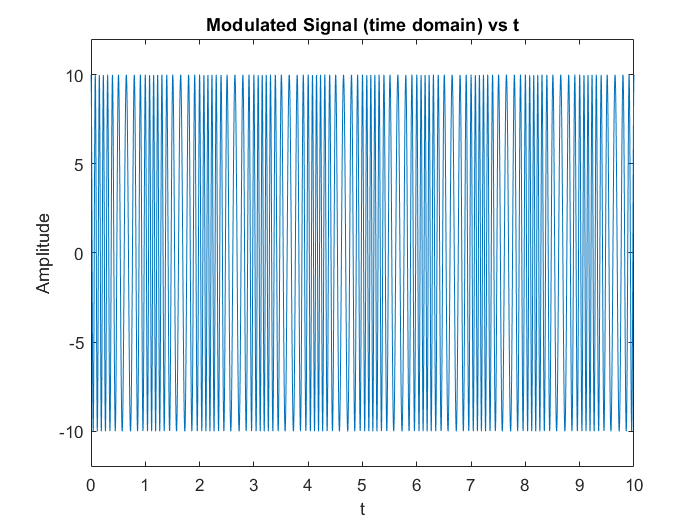

% assuming kf=1
kf=1;
% finding theta using cumulative sum
theta=2*pi*kf*(cumsum(m)/fs);
% theta(t==0) should be 0
% but cumsum() does not give theta(t==0)=0
% reducing theta by theta(t==0) to make theta(t==0)=0
theta=theta-theta(t==0);
%=============================================
% % we can also find integration using integral() function
% % finding theta from integration of m(t)
% % decaring a function m(t) in terms of x
% fun=@(x) 3*sin(2*pi*x)+2*cos(2*pi*x);
% for i =1:length(t);
% %      finding theta for each value of t using integral() function
% %      integration from 0 to t
%    theta(i)=2*pi*kf*integral(fun,0,t(i));
% end;
%=============================================
% NOTE: Both cumsum()/fs and integral() produce the exact same output
% ============================================
Ac=10; % consider Ac=10
% time domain modulated signal array
mod=Ac*cos(2*pi*fc*t+theta(t==0)+theta);
% plotting time domain modulated signal
plot(t,mod)
title("Modulated Signal (time domain) vs t");
ylabel("Amplitude");
xlabel("t")
ylim([-1.2*Ac Ac*1.2]);% y limits changed for better plot

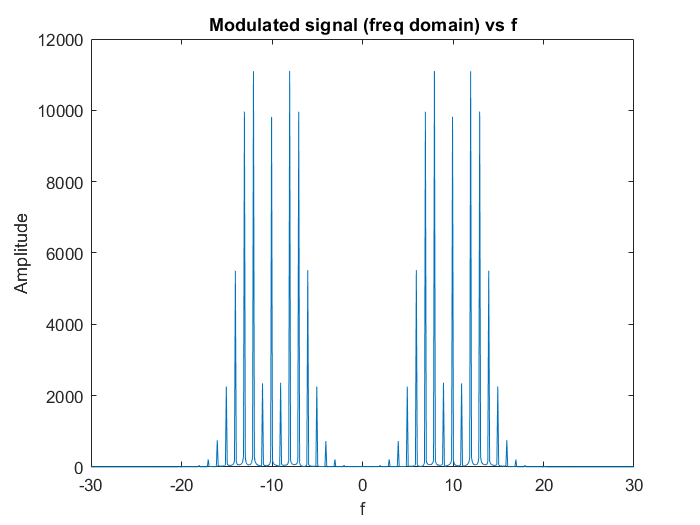

U=fftshift(fft(mod)); % fourier transform of modulated signal array
n=length(U); % no of elements of U
f=(-n/2:n/2-1)*fs/n; % freq component array of modulated signal
% plotting freq domain modulated signal
plot(f,abs(U))
xlabel('f');
ylabel('Amplitude');
xlim([-3*fc 3*fc]);% x limits changed for better plot
title('Modulated signal (freq domain) vs f');

### Demodulation and plots

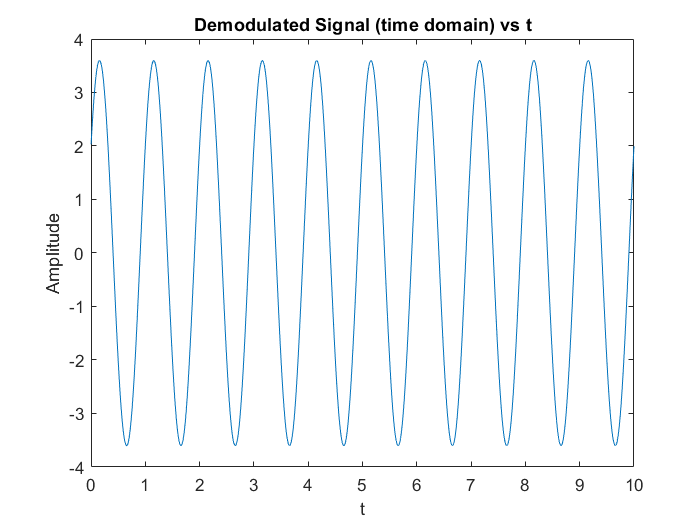

% array containing diffentiation of modulated signal wrt t
% diff() func reduces length of array by 1
diff_mod=diff(mod)*fs;
% envelope detection of differentiated signal
env_diff=envelope(-1*diff_mod);
% DC component can be removed by subtracting mean of signal
% removing mean of envelope signal to get DC filtered signal
pass_demod=env_diff-mean(env_diff);
% rescaling to get message signal
demod=pass_demod/(2*pi*Ac*kf);
% new time scale excluding 0
t1=t(2:end);
% plotting demodulated signal
plot(t1,demod)
title("Demodulated Signal (time domain) vs t");
ylabel("Amplitude");
xlabel("t")

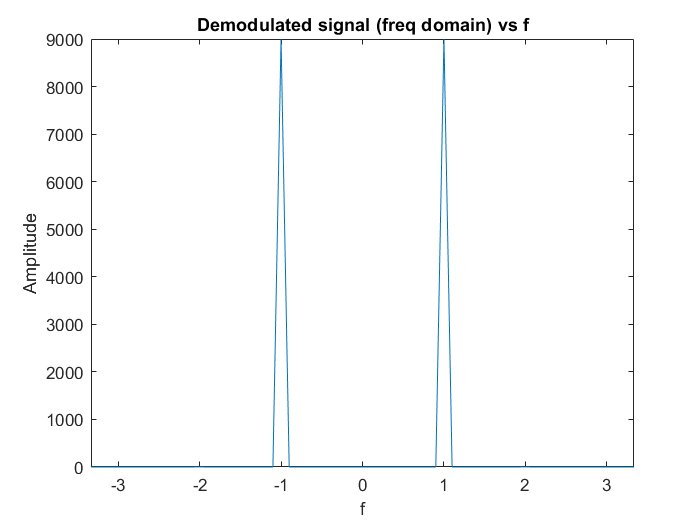

DMD=fftshift(fft(demod));% fourier transform of demodulated signal array
n=length(DMD); % no of elements of DMD
f=(-n/2:n/2-1)*fs/n; % freq component array of demodulated signal
% plotting freq domain demodulated signal
plot(f,abs(DMD))
xlabel('f');
ylabel('Amplitude');
xlim([-fc/3 fc/3]);% x limits changed for better plot
title('Demodulated signal (freq domain) vs f');

## Conclusion:

The demodulated signal has same time-domain and freq-domain plots as the message signal.